%% ============================================================
%% CLEAN ARM MESH + MEMORY-SAFE VOXELIZATION
%% ============================================================

clear; clc; close all;

%% -------- SELECT OBJ FILE --------
[filename, pathname] = uigetfile('*.obj','Select an OBJ file');
if isequal(filename,0)
    return;
end
filepath = fullfile(pathname, filename);

%% -------- READ OBJ --------
fid = fopen(filepath,'r');
V = [];
F = [];

while ~feof(fid)
    line = strtrim(fgetl(fid));
    if length(line)<2, continue; end

    if line(1)=='v' && line(2)==' '
        V(end+1,:) = sscanf(line(2:end),'%f %f %f')';
    elseif line(1)=='f' && line(2)==' '
        tokens = strsplit(strtrim(line(2:end)));
        face = zeros(1,length(tokens));

        for k=1:length(tokens)
            parts = strsplit(tokens{k},'/');
            face(k) = str2double(parts{1});
        end

        if numel(face)==3
            F(end+1,:) = face;
        elseif numel(face)==4
            F(end+1,:) = face([1 2 3]);
            F(end+1,:) = face([1 3 4]);
        end
    end
end
fclose(fid);

%% -------- AUTO-SCALE TO METERS (if mesh is mm) --------
bbox = max(V) - min(V);
if max(bbox) > 2     % larger than 2 meters? likely mm
    disp('Detected millimeter units. Converting to meters...')
    V = V * 1e-3;
end

Detected millimeter units. Converting to meters...


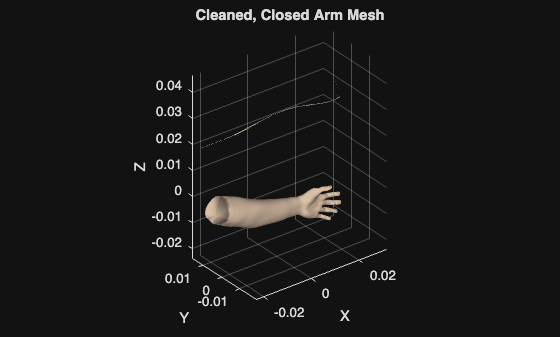


%% -------- BUILD CONNECTIVITY --------
edges = [F(:,[1 2]); F(:,[2 3]); F(:,[3 1])];
edges = sort(edges,2);
faceIDs = repelem((1:size(F,1))',3);

[~,~,g] = unique(edges,'rows');
adj = sparse(size(F,1),size(F,1));
for k = unique(g)'
    f = faceIDs(g==k);
    if numel(f)>1
        adj(f,f) = 1;
    end
end
adj = adj - diag(diag(adj));

G = graph(adj);
compID = conncomp(G)';
numComp = max(compID);

%% -------- KEEP LARGEST SPATIAL COMPONENT --------
diagLen = zeros(numComp,1);

for c = 1:numComp
    Fc = F(compID==c,:);
    verts = unique(Fc(:));
    Vc = V(verts,:);
    box = max(Vc) - min(Vc);
    diagLen(c) = norm(box);
end

[~,keep] = max(diagLen);
F = F(compID==keep,:);
[V,F] = removeUnusedVertices(V,F);

%% -------- CLOSE OPEN BOUNDARIES --------
TR = triangulation(F,V);
boundaryEdges = freeBoundary(TR);

if ~isempty(boundaryEdges)
    loops = buildBoundaryLoops(boundaryEdges);

    for L = 1:numel(loops)
        b = loops{L};
        center = mean(V(b,:),1);
        V = [V; center];
        cIdx = size(V,1);

        for i = 1:numel(b)
            v1 = b(i);
            v2 = b(mod(i,numel(b))+1);
            F(end+1,:) = [v1 v2 cIdx];
        end
    end
end

%% -------- DISPLAY CLEANED MESH --------
figure;
p = patch('Vertices',V,'Faces',F);
set(p,'FaceColor',[0.85 0.75 0.65], ...
      'EdgeColor','none', ...
      'FaceLighting','gouraud');

axis equal
grid on
xlabel('X'); ylabel('Y'); zlabel('Z');
view(3)
camlight headlight
material dull
rotate3d on
title('Cleaned, Closed Arm Mesh')


%% ============================================================
%% MEMORY-SAFE VOXELIZATION
%% ============================================================

disp('Starting voxelization...')

Starting voxelization...



voxelSize = 0.002;   % 2 mm resolution

xmin = min(V(:,1)); xmax = max(V(:,1));
ymin = min(V(:,2)); ymax = max(V(:,2));
zmin = min(V(:,3)); zmax = max(V(:,3));

x = xmin:voxelSize:xmax;
y = ymin:voxelSize:ymax;
z = zmin:voxelSize:zmax;

Nx = numel(x);
Ny = numel(y);
Nz = numel(z);

fprintf('Grid size: %d x %d x %d\n', Nx, Ny, Nz)

Grid size: 28 x 15 x 33



volumeMask = false(Ny, Nx, Nz);

for k = 1:Nz
    zk = z(k);

    [X,Y] = meshgrid(x,y);
    Z = zk * ones(size(X));

    pts = [X(:) Y(:) Z(:)];

    inside = inpolyhedron(F,V,pts);

    volumeMask(:,:,k) = reshape(inside, Ny, Nx);

    if mod(k,10)==0
        fprintf('Slice %d / %d\n', k, Nz);
    end
end

Slice 10 / 33
Slice 20 / 33
Slice 30 / 33



disp('Voxelization complete.')

Voxelization complete.


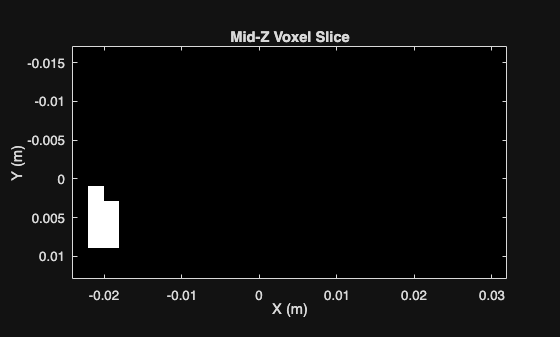


%% -------- SHOW MID-SLICE --------
figure;
imagesc(x,y,volumeMask(:,:,round(Nz/2)));
axis equal tight
colormap gray
xlabel('X (m)')
ylabel('Y (m)')
title('Mid-Z Voxel Slice')

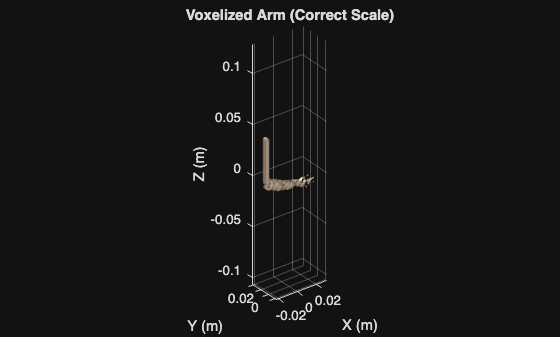


%% ============================================================
%% 3D VOXEL VISUALIZATION
%% ============================================================

%% 3D VOXEL VISUALIZATION (FIXED)

[Xg, Yg, Zg] = meshgrid(x, y, z);

figure;

p = patch(isosurface(Xg, Yg, Zg, volumeMask, 0.5));

set(p, 'FaceColor', [0.85 0.75 0.65], ...
       'EdgeColor', 'none');

isonormals(Xg, Yg, Zg, volumeMask, p)

axis equal
grid on
view(3)
camlight headlight
lighting gouraud
xlabel('X (m)')
ylabel('Y (m)')
zlabel('Z (m)')
title('Voxelized Arm (Correct Scale)')



%% ============================================================
%% HELPER FUNCTIONS
%% ============================================================

function [Vnew,Fnew] = removeUnusedVertices(V,F)
    used = unique(F(:));
    Vnew = V(used,:);
    map = zeros(size(V,1),1);
    map(used)=1:length(used);
    Fnew = map(F);
end

function loops = buildBoundaryLoops(edges)
    E = edges;
    loops = {};

    while ~isempty(E)
        loop = E(1,:);
        E(1,:) = [];

        while true
            last = loop(end);
            idx = find(E(:,1)==last | E(:,2)==last,1);
            if isempty(idx), break; end

            if E(idx,1)==last
                next = E(idx,2);
            else
                next = E(idx,1);
            end

            loop(end+1) = next;
            E(idx,:) = [];
        end

        loops{end+1} = unique(loop,'stable');
    end
end
